clear all; close all; clc;

% 125 136
% 20 20
pixel_observation_x = 125

pixel_observation_x = 125

pixel_observation_y = 136

pixel_observation_y = 136


sample_count =199

sample_count = 199

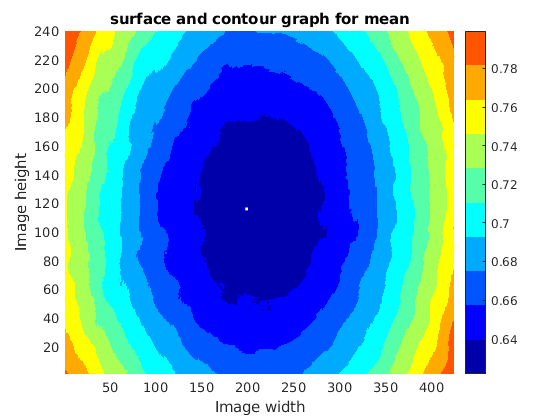

width = 424;
height = 240;
path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/carpet/carpet_wo_glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

sample_vector_truth = zeros(sample_count,1);

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    matrix_mean = zeros(height,width);
    avg_mean_col = data(:,4);
    
    i=1;
    for cImage_x = 1:height
        for rImage_y = 1:width
            matrix_mean(cImage_x,rImage_y) = avg_mean_col(i);
            
            i = i+ 1;
        end
    end
    v = matrix_mean(pixel_observation_y,pixel_observation_x);
    
    sample_vector_truth(callback_count) = v;
    
    if(callback_count<=2)
        % surfc for the mean
        x = 1:width;
        y = 1:height;
        z = matrix_mean;
        [X1,X2]=meshgrid(x,y);
        surfc(X1,X2,z)
        
        grid on
        view(2)
        title('surface and contour graph for mean')
        xlabel('Image width')
        ylabel('Image height')
        zlabel('mean')
        shading interp
        colormap (jet(10))
        colorbar
        saveas(gcf,'image_map_for_callback_0_.png')
        
    end
end

sample_vector_truth

sample_vector_truth =     0.6488
    0.6467
    0.6467
    0.6477
    0.6467
    0.6456
    0.6456
    0.6477
    0.6477
    0.6488


ground_truth = mean(sample_vector_truth)

ground_truth = 0.6464

ground_truth_std = nanstd(sample_vector_truth)

ground_truth_std = 0.0014

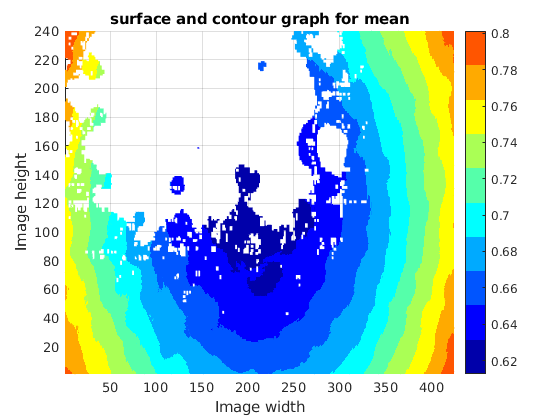



path_pefix ="/home/sur/catkin_ws/src/d435_characterization/rosbag/carpet/carpet_glare/beforeCSV_file_for_cloud_";
path_postfix = ".csv";

sample_vector_glare = zeros(sample_count,1);

for callback_count = 1:sample_count
    
    h = string(callback_count);
    path = path_pefix+h+path_postfix;
    data = csvread(path);
    
    matrix_mean = zeros(height,width);
    avg_mean_col = data(:,4);
    
    i=1;
    for cImage_x = 1:height
        for rImage_y = 1:width
            matrix_mean(cImage_x,rImage_y) = avg_mean_col(i);
            
            i = i+ 1;
        end
    end
    v = matrix_mean(pixel_observation_y,pixel_observation_x);
    
    sample_vector_glare(callback_count) = v;
    
    if(callback_count<=2)
        % surfc for the mean
        x = 1:width;
        y = 1:height;
        z = matrix_mean;
        [X1,X2]=meshgrid(x,y);
        surfc(X1,X2,z)
        
        grid on
        view(2)
        title('surface and contour graph for mean')
        xlabel('Image width')
        ylabel('Image height')
        zlabel('mean')
        shading interp
        colormap (jet(10))
        colorbar
        saveas(gcf,'image_map_for_callback_0_.png')
        
    end
end


sample_vector_glare

sample_vector_glare =     0.6456
    0.6446
    0.6425
    0.6467
       NaN
    0.6446
    0.6446
    0.6425
    0.6446
    0.6436


sample_mean = nanmean(sample_vector_glare)

sample_mean = 0.6451

sample_std = nanstd(sample_vector_glare)

sample_std = 0.0013


no_of_nan = sum(isnan(sample_vector_glare))

no_of_nan = 139

if(sample_count - no_of_nan >30)
    z_score = (ground_truth - sample_mean)*sqrt(sample_count)/sample_std
else
    t = "not enough points to get z score"
    
end

z_score = 13.6550